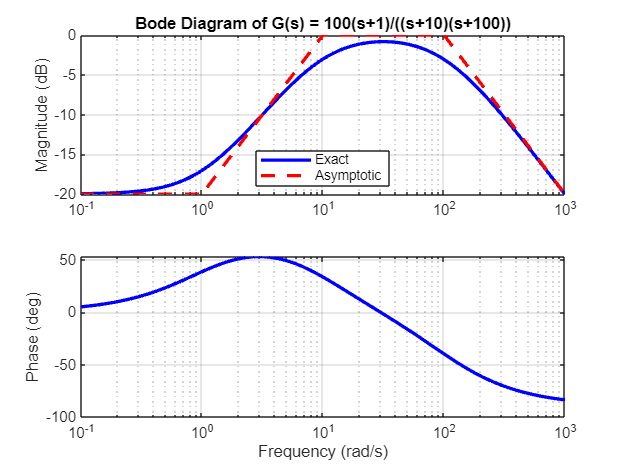

% EE352 Automatic Control Assignment 
%
% Student Name: [Perera J.D.T.]
% Registration Number: [E/21/291]
% Date: [2026-02-19]

clc;
clear;
close all;

% G(s) = 100(s+1)/((s+10)(s+100))
s = tf('s');
num = 100 * (s + 1);
den = (s + 10) * (s + 100);
G = num / den;

%% 1.Diagram 
figure('Name', 'Bode Diagram Analysis');
opts = bodeoptions;
opts.FreqUnits = 'rad/s';
opts.PhaseMatching = 'on';
opts.Grid = 'on';

% Calculate exact Bode data
[mag, phase, w] = bode(G, {0.1, 1000});
mag_db = 20*log10(squeeze(mag));
phase_deg = squeeze(phase);

subplot(2,1,1);
semilogx(w, mag_db, 'b-', 'LineWidth', 2); hold on;
title('Bode Diagram of G(s) = 100(s+1)/((s+10)(s+100))');
ylabel('Magnitude (dB)');
grid on;

subplot(2,1,2);
semilogx(w, phase_deg, 'b-', 'LineWidth', 2); hold on;
ylabel('Phase (deg)');
xlabel('Frequency (rad/s)');
grid on;

%% 2. Asymptotic Bode 

w_asymp = [0.1, 1, 10, 100, 1000];
mag_asymp = zeros(size(w_asymp));
mag_asymp(1) = -20; % Start at -20 dB (flat until first corner)
mag_asymp(2) = -20; % Zero at w=1
mag_asymp(3) = -20 + 20*log10(10/1); % Slope +20 dB/dec from w=1 to w=10. Result: 0 dB
mag_asymp(4) = 0 + (20-20)*log10(100/10); % Slope 0 dB/dec from w=10 to w=100. Result: 0 dB
mag_asymp(5) = 0 + (0-20)*log10(1000/100); % Slope -20 dB/dec from w=100. Result: -20 dB

subplot(2,1,1);
semilogx(w_asymp, mag_asymp, 'r--', 'LineWidth', 2);
legend('Exact', 'Asymptotic', 'Location', 'Best');


fprintf('\n--- Asymptotic Analysis ---\n');


--- Asymptotic Analysis ---


fprintf('Standard Form: G(s) = 0.1 * (s+1) / [(0.1s+1)(0.01s+1)]\n');

Standard Form: G(s) = 0.1 * (s+1) / [(0.1s+1)(0.01s+1)]


fprintf('DC Gain (K): 0.1 => 20*log10(0.1) = -20 dB\n');

DC Gain (K): 0.1 => 20*log10(0.1) = -20 dB


fprintf('Corner Frequencies:\n');

Corner Frequencies:


fprintf('  w_z1 = 1 rad/s (Zero) => Slope changes by +20 dB/dec\n');

  w_z1 = 1 rad/s (Zero) => Slope changes by +20 dB/dec


fprintf('  w_p1 = 10 rad/s (Pole) => Slope changes by -20 dB/dec\n');

  w_p1 = 10 rad/s (Pole) => Slope changes by -20 dB/dec


fprintf('  w_p2 = 100 rad/s (Pole) => Slope changes by -20 dB/dec\n');

  w_p2 = 100 rad/s (Pole) => Slope changes by -20 dB/dec


fprintf('\nAsymptotic Plot Logic:\n');


Asymptotic Plot Logic:


fprintf('  w < 1:   Magnitude = -20 dB (Slope 0)\n');

  w < 1:   Magnitude = -20 dB (Slope 0)


fprintf('  1 < w < 10: Slope = +20 dB/dec. Rise from -20 dB to 0 dB.\n');

  1 < w < 10: Slope = +20 dB/dec. Rise from -20 dB to 0 dB.


fprintf('  10 < w < 100: Slope = +20 - 20 = 0 dB/dec. Constant at 0 dB.\n');

  10 < w < 100: Slope = +20 - 20 = 0 dB/dec. Constant at 0 dB.


fprintf('  w > 100: Slope = 0 - 20 = -20 dB/dec. Fall from 0 dB.\n');

  w > 100: Slope = 0 - 20 = -20 dB/dec. Fall from 0 dB.
